# MECH3465 | Coursework 2: Template

Replace the template title with your teams number!

## CW2: Coursework 2 - ** Robot Librarian!**

This coursework template is split into the 5 sections of the coursework.

**If you haven't read the brief then please download it from minerva**

You should explain your process during each stage, and each section of code you include should contain a short description of what you are doing and an overview of any MATLAB functions you have used and why.

### Add your own sub-headings to each main section!

This will keep things organised.

### Comment your code!

Before you say anything, I will admit my code has been quite poorly commented in some cases throughout the practicals, don't be like me, comment your code!

## 0. Loading the Scenario

Download the URDF file from Minerva and save it somewhere, be aware that if you all work on the code together the file path may change depending on who's PC you are using and where they have saved the files!

clear   % Clear workspace variables
clc % Clear Command Window

Create a [`robotScenario`](docid:robotics_ref#mw_146ff228-e368-41e9-ac10-b70d38e44bd8) object.

scenario = robotScenario(UpdateRate=1, StopTime=10);

Create a [`rigidBodyTree`](docid:robotics_ref#bvan8uq-1) object of the custom CW2 URDF.

%addpath("C:\Users\dnehu\Documents\University\Year 3\Engineering\MECH3465 - Robotics & Machine Intelligence\Robotics\Coursework 2\URDFs\Robot_URDF_Visuals\urdf")  % Dan path folder
addpath("C:\Users\mn22dn\OneDrive - University of Leeds\Robotics Coursework\URDFs\Robot_URDF_V2\urdf")     % Uni Computer
%addpath("/Users/louieburns/Library/CloudStorage/OneDrive-UniversityofLeeds/Robotics Coursework/URDFs/Robot_URDF_Visuals/urdf")  % Louie Path folder
savepath % Save filepath for next time

% Import the robot model from the URDF file (using the rigidBodyTree object)
robotRBT = importrobot("Robot_URDF_V2.urdf");
robotRBT.DataFormat = "row"  % or use "column" if you prefer

robotRBT =   rigidBodyTree with properties:

     NumBodies: 5
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Link_1'  'Link_2'  'Link_3'  'Link_4'  'End_Effector'}
      BaseName: 'Base_Link'
       Gravity: [0 0 0]
    DataFormat: 'row'


Create a `rigidBodyTree`-based [`robotPlatform`](docid:robotics_ref#mw_184989ef-41a5-4055-a8a4-5460899dbc3a) object using the manipulator model.

Robot = robotPlatform("Manipulator",scenario, RigidBodyTree=robotRBT);

Create collision objects for all 6 books. - DO NOT EDIT BOOK POSITIONS IN THIS SECTION

book_1 = robotPlatform("Book_1",scenario,Collision="mesh", InitialBaseOrientation=[0.706923132	0.706925728	0.016057751	0.016057692], InitialBasePosition=[0.014018	-0.30839	0.10381]);
updateMesh(book_1,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 0])

book_2 = robotPlatform("Book_2",scenario,Collision="mesh", InitialBaseOrientation=[0.706747289	0.706749885	0.022504157	0.022504074], InitialBasePosition=[-0.019668	0.30852	-0.032738]);
updateMesh(book_2,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0.682 0])
 
book_3 = robotPlatform("Book_3",scenario,Collision="mesh", InitialBaseOrientation=[0.40083391	0.400835382	-0.582522818	-0.582520678], InitialBasePosition=[0.28417	-0.10873	-0.082996]);
updateMesh(book_3,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 1 0])

book_4 = robotPlatform("Book_4",scenario,Collision="mesh", InitialBaseOrientation=[0.206562054	0.206562812	0.676264476	0.676261992], InitialBasePosition=[-0.16721	-0.24817	0.32703]);
updateMesh(book_4,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 0])

book_5 = robotPlatform("Book_5",scenario,Collision="mesh", InitialBaseOrientation=[0.636410903	0.636413241	0.308188293	0.308187161], InitialBasePosition=[-0.24541	0.19397	0.10258]);
updateMesh(book_5,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 1])

book_6 = robotPlatform("Book_6",scenario,Collision="mesh", InitialBaseOrientation=[0.276366618	0.276367633	0.650863095	0.650860704], InitialBasePosition=[-0.22945	-0.22148	0.10258]);
updateMesh(book_6,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 1])

Visualize the scenario (books and environment).

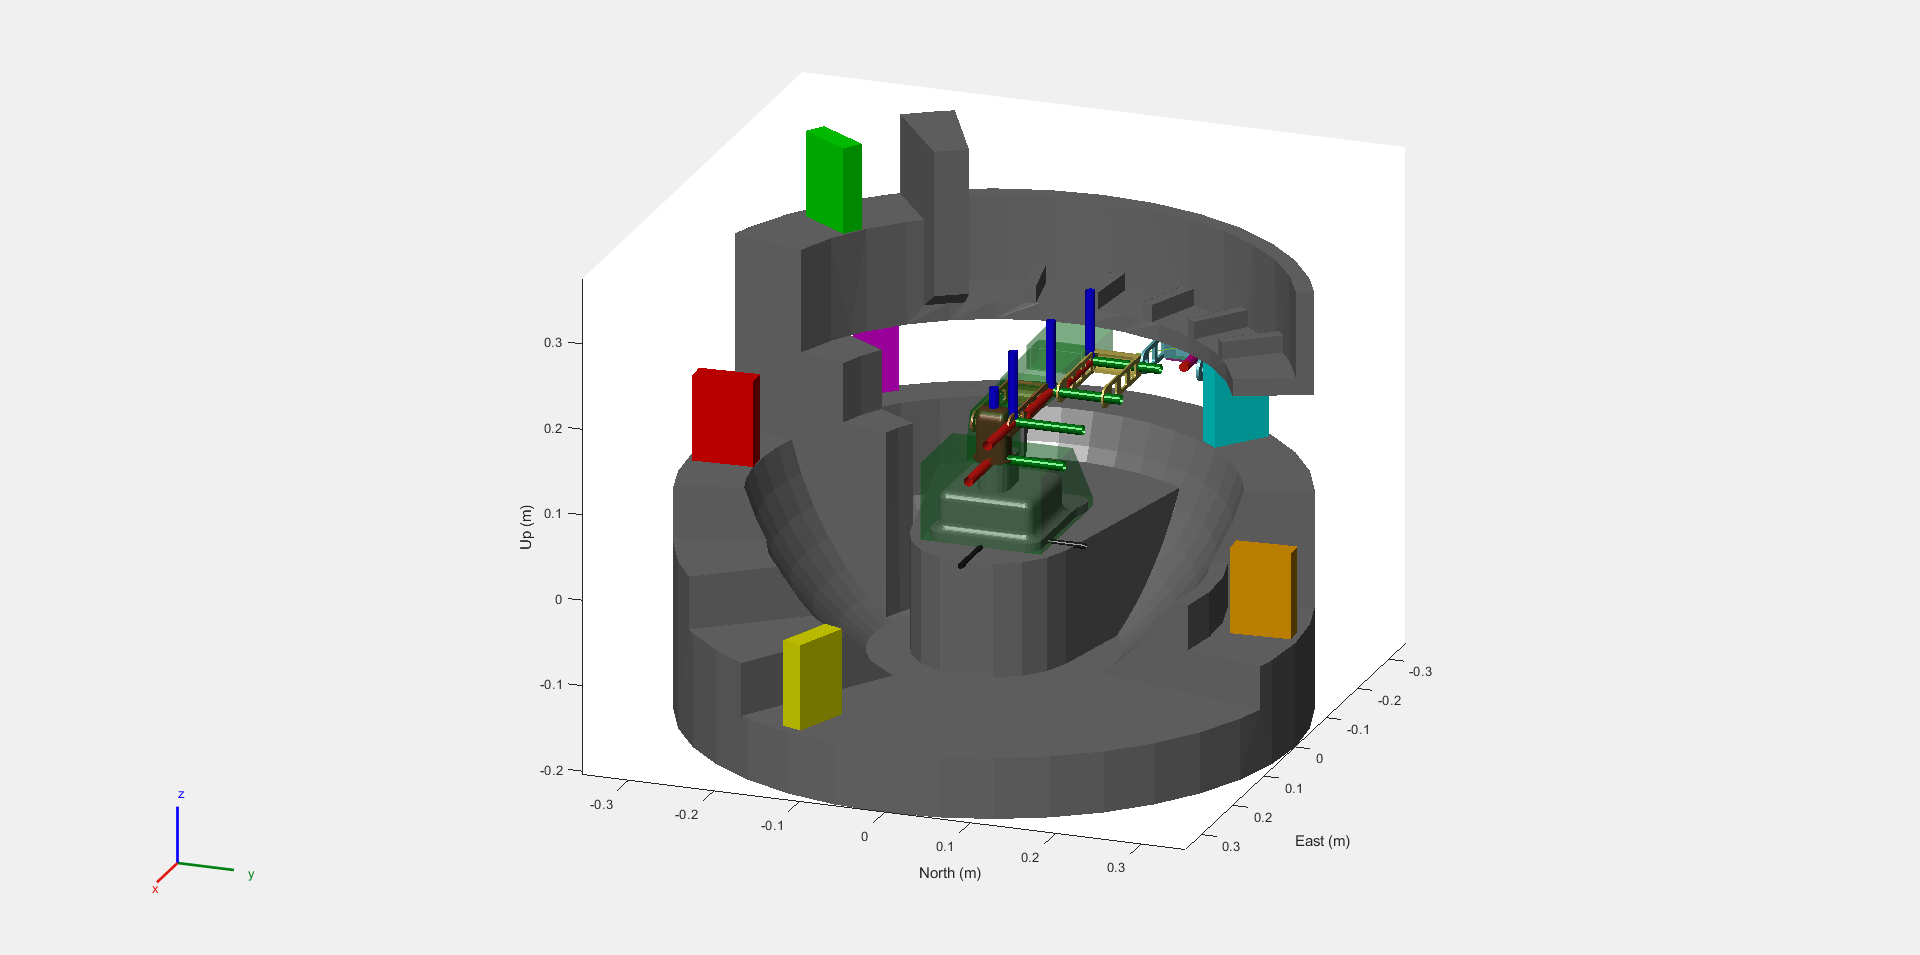

[ax,plotFrames] = show3D(scenario,Collisions="on");
view(ax, 110, 20);
axis equal
light
drawnow;
hold on;

## 1. Forward Kinematics

### 1.1 Approach Overview

In order to calculate the forward kinematics of our 4DOF robot arm, we followed a step-by-step process using the Denavit-Hartenberg (D-H) convention. Here's how we went about it:

**Started with the robot schematic**

- We took a close look at the Robot Dimensions document to get a feel for how the arm is built. This helped us pull out all the key measurements we needed.

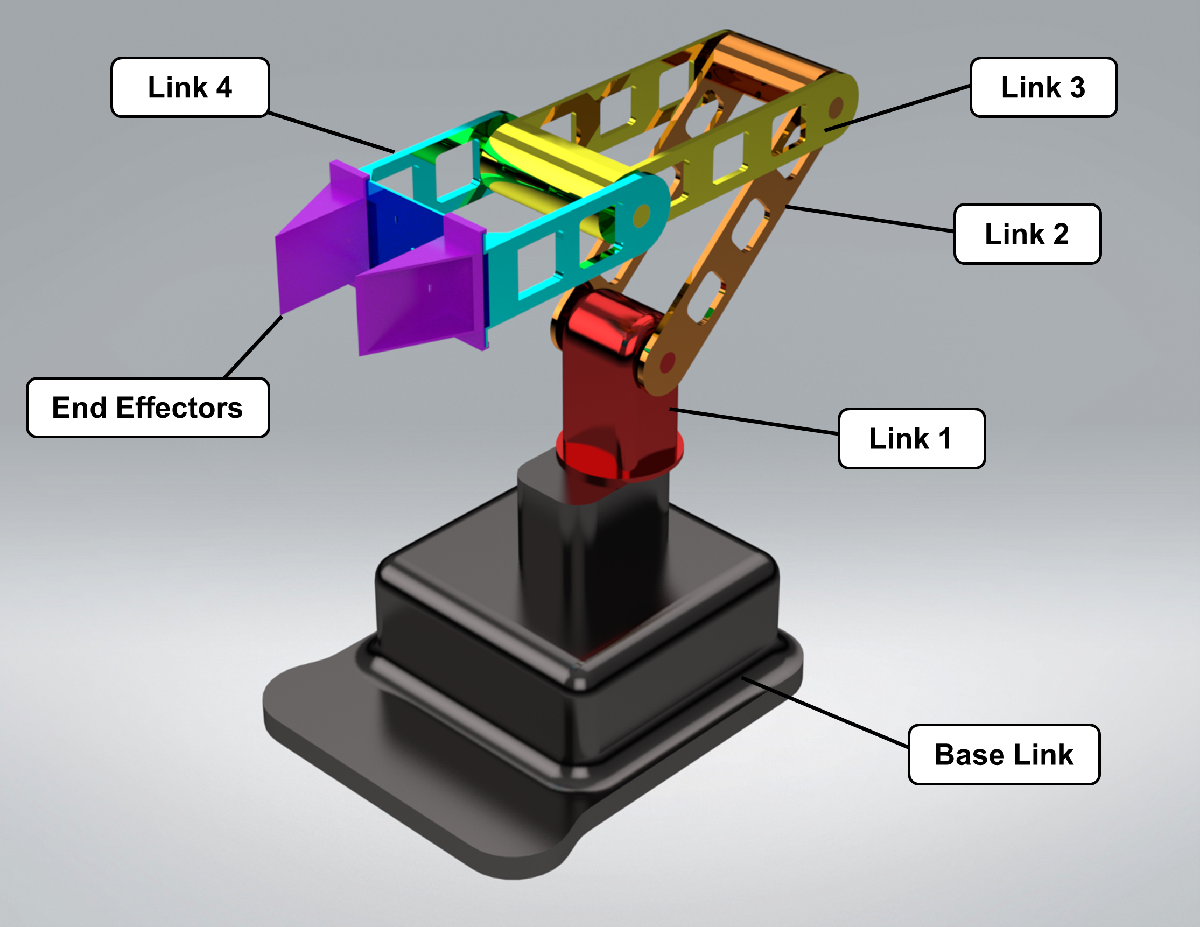

**Assigned coordinate frames to each joint**

- Using the D-H method, we added coordinate frames to every joint in a systematic way. This let us define the four main D-H parameters:

- θ (joint angle)

- d (link offset)

- a (link length)

- α (link twist)

**Built the D-H table**

- Once the frames were set, we pulled all the parameters together into a D-H table. This table basically maps out how each link connects to the next.

**Modelled it in MATLAB**

- We used MATLAB’s `rigidBodyTree` object to create the robot model based on our D-H table. This made it easy to simulate the robot’s motion and see how everything moved together.

**Did a visual check**

- Finally, we visualised the robot in MATLAB to make sure everything lined up. We checked the home position and confirmed that all the coordinate frames looked right compared to the schematic.

### 1.2 Labelled Denavit-Hartenberg Frame Diagram

Download the CW2_Robot_Dimensions.PDF from Minerva and use it to solve the forward kinematics of the robot using the Denavit-Hartenberg assignment method. For more information look at back at the lecture on Forward Kinematics, it has a breakdown of the solutions.

Insert D-H Diagram

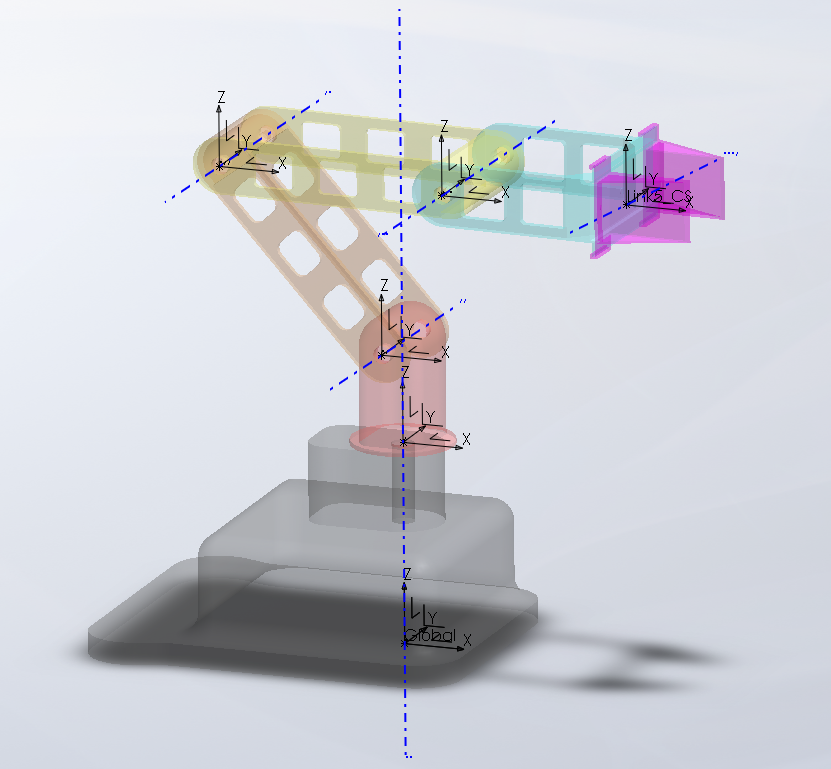

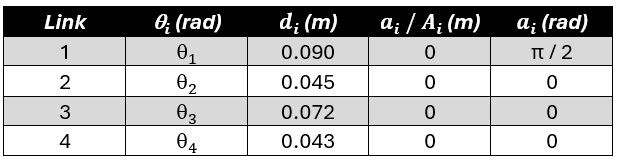

### 1.3 Specify D-H Parameters and Produce a Table

To model the kinematic structure of our 4DOF robot arm, we used the Denavit-Hartenberg (D-H) convention to define the relative transformations between adjacent joints. This approach ensures a structured representation of the robot’s geometry and joint orientations. All parameters were obtained from the schematic in Robot Dimensions.pdf and verified against the robot model imported from the URDF.

We used the standard D-H convention, where:

- θ_i is the joint variable (rotation about Z-axis for revolute joints),

- d_i is the offset along Z_i,

- a_i is the length along X_i,

- α_i is the twist between Z_i and Z_i+1 around X_i.


$$\textrm{dhparams}\;\textrm{in}\;\textrm{Lecture}\;\;\;\;\;\;=\left\lbrack \;\;\;\;\;\theta {\;}_{i\;} \;\;\;\;\;|\;\;d_{i\;} \;\;\;\;\;\;|\;\;\;\;A_{i\;} /a_{i\;} \;\;\;\;|\;\;\;\;\alpha_{i\;} \;\;\;\right\rbrack$$



$$\textrm{dhparams}\;\textrm{in}\;\textrm{MATLAB}\;=\left\lbrack {\;\;A}_{i\;} /a_{i\;} \;\;\;|\;\;\;\;\alpha_{i\;} \;\;\;\;\;\;|\;\;\;\;d_{i\;} \;\;\;\;|\;\;\;\;\theta {\;}_{i\;} \;\;\right\rbrack$$


dhparams = [ 0       pi/2    0.090   0;
             0       0       0.045   0;
             0       0       0.072   0;
             0       0       0.043   0 ];

% Show table in Live Script
disp('D-H Parameters:');

D-H Parameters:


disp(dhparams);

         0    1.5708    0.0900         0
         0         0    0.0450         0
         0         0    0.0720         0
         0         0    0.0430         0



**Explanation of Frame Assignment and D-H Choices**

We carefully followed the D-H convention when assigning frames. Starting from the base, the Z-axes were aligned with the axes of rotation for each joint. The first frame required a twist of **π/2 radians** to align the X-axis properly with the shoulder joint plane. Each subsequent frame was placed at the intersection of adjacent joint axes or along the link offset, based on physical dimensions derived from the CAD model and URDF.

All link lengths and offsets were measured in millimetres and converted to metres. For example:

- The **0.090 m** offset in Link 1 corresponds to the vertical height from the base to the shoulder joint.

- The following offsets (0.045, 0.072, 0.043) represent vertical separations between joints, consistent with the robot’s planar architecture.

## 2. Build Robot in MATLAB Robotics Toolbox

### **2.1 Approach Explanation and Notes**

We chose to design our robot in SolidWorks for greater control over the mechanical layout and visual fidelity. Once the mechanical structure was finalised, we exported the model as a URDF file. This allowed us to directly import the robot into MATLAB without needing to manually define each link using D-H parameters. This approach also enabled us to focus more on trajectory generation and animation within the simulation environment.

We then added a collision sphere to the tool centre point (TCP) of the end-effector using both `addCollision` and `addVisual`. This 5 mm sphere is used to detect contact with books in the interactive environment. Visual geometry was retained from the URDF, though additional visual primitives could have been added if needed.

The robot was displayed using the `show()` function in its home configuration. Any required changes to this configuration were made via the `homeConfiguration` array, which stores the default joint angles. We verified that the imported robot model had all links and joints properly loaded using `showdetails(robotRBT)`.

% Our robot was created in SolidWorks and exported as a URDF

### 2.2 Setup Variables

% Key Co-ordinates
zero_congif = [0,0,0,0];
homeconfig = [180, -90, 90, -90];
centre = [-0.00029, 0.00037];
book_straight_collect_offset = 0.027;

% Link Lengths
L1 = 0.135;   
L2 = 0.107;  
L3 = 0.107; 
L4 = 0.109; 

% Number of interpolation steps
numSteps = 10;
numSteps_mid = 1;
numSteps_straight = 20;

% Scale for the mid-points for each book position
num_mid_points = 10;
radius_scale = 0.6;

%Offset for shelf height
height_shelf_offset = 0.01;

% Red book base swivel to avoid shelf
mid_point = [90	-90	90	90];

%% BOOK TRANSLATION

% how much to shift (in metres)
leftShift   = 0.005;   % 5 mm to the left (already perfect)
upShift     = 0.005;   % 5 mm upward

% how much to pull the book away from the gripper
depthShift  = -0.01;   % 10 mm inward

% apply left, up, AND depth tweaks
translation = trvec2tform([
    -0.03 + depthShift,   ... % X: shallower by 5 mm
    -0.02 + leftShift,    ... % Y: left/right
    -0.021 + upShift      ... % Z: up/down
]);

% keep your existing rotations
rotationX = axang2tform([1 0 0 pi/2]);
rotationZ = axang2tform([0 0 1 pi/2]);

% combine exactly as before
customTransform = translation * rotationZ * rotationX;

### 2.3 Adding Robot Collisions 

% We add a collision sphere to the TCP (end-effector) for detecting contact.
showdetails(robotRBT)

--------------------
Robot: (5 bodies)

 Idx           Body Name    Joint Name    Joint Type           Parent Name(Idx)   Children Name(s)
 ---           ---------    ----------    ----------           ----------------   ----------------
   1              Link_1        Joint1      revolute               Base_Link(0)   Link_2(2)  
   2              Link_2        Joint2      revolute                  Link_1(1)   Link_3(3)  
   3              Link_3        Joint3      revolute                  Link_2(2)   Link_4(4)  
   4              Link_4        Joint4      revolute                  Link_3(3)   End_Effector(5)  
   5        End_Effector        Joint5         fixed                  Link_4(4)   
--------------------


home = homeConfiguration(robotRBT);

% ax = show(robotRBT, "Frames","off", "Collisions","off"); % Check robot loaded correctly

% Add collison to the end effector of your robot
addCollision(robotRBT.Bodies{end},"sphere",0.005, trvec2tform([0,0,0])) % add new collision
addVisual(robotRBT.Bodies{end},"sphere",0.005, trvec2tform([0,0,0]))

isColliding = checkCollision(robotRBT, homeConfiguration(robotRBT), IgnoreSelfCollision="off");


% Possibly useful functions: 
clearCollision(robotRBT.Bodies{1,4})

### 2.4 Visualising the Scene

% Show scene once at the start
hold off

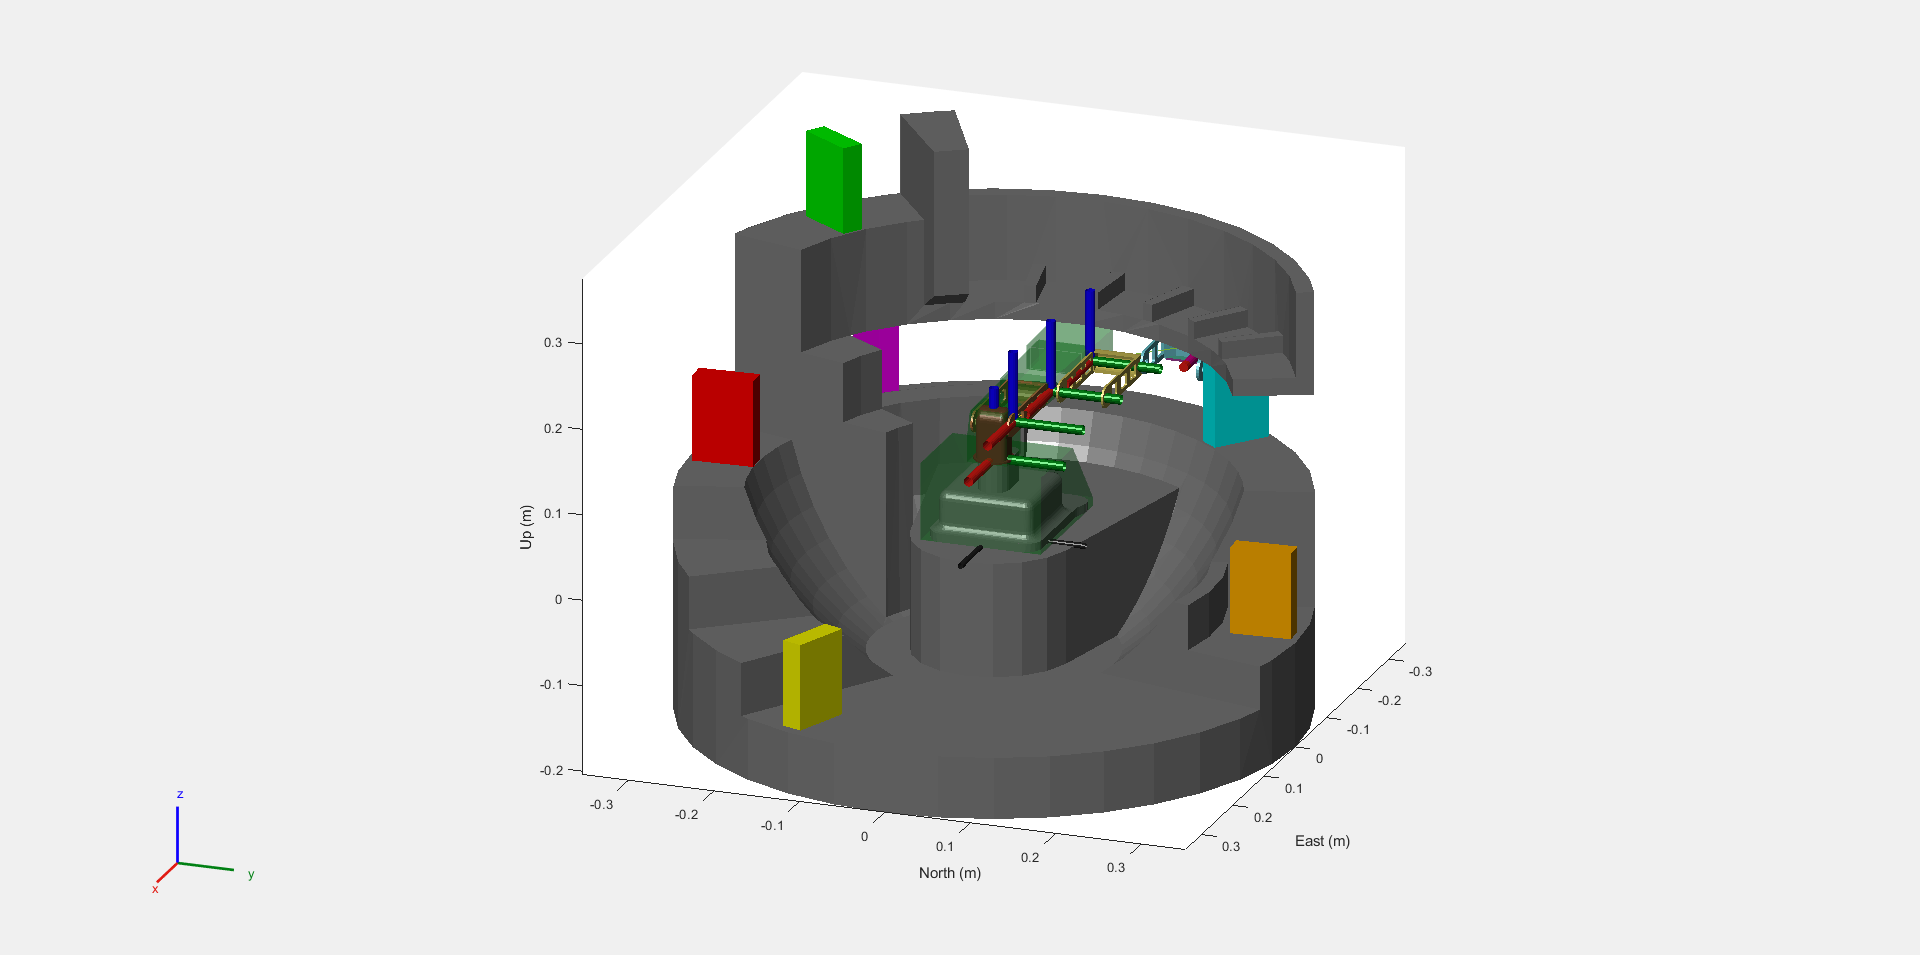

[ax, plotFrames] = show3D(scenario, Collisions="on");
[az, el] = view(ax);
view (ax, 110, 20)
axis equal
light
drawnow
hold on

## 3. Inverse Kinematics

Starting in the home configuration, solve for the arm reaching the point where the Book_1 frame lies.

### 3.1 Explain your Approach 

To solve the inverse kinematics (IK) for our custom 4DOF robot, we used a geometric (analytical) method, with the following key steps and assumptions:

**Robot Structure**: A 4DOF planar robot with three revolute joints for positioning and one for orientation. The final joint maintains a fixed gripper angle.

**Joint Calculation**:

- **θ₁**: Computed using `atan2(y, x)` for base rotation.

- **θ₂ & θ₃**: Solved using the cosine rule and triangle geometry from the wrist position.

- **θ₄**: Calculated to keep the end-effector horizontal: `θ₄ = -(θ₂ + θ₃)`.

**Wrist Offset**: We accounted for the physical offset of the end-effector by subtracting its length before solving the geometry.

**Assumptions**:

- The robot operates in a known, static environment.

- IK targets are reachable and not obstructed.

- The end-effector orientation is fixed (horizontal) for book grasping and placing.

**Comparison to 3DOF Robots**:

- Our approach is similar in principle but includes an extra joint for end-effector control.

- This extra degree of freedom improves precision for object handling, especially orientation alignment.

### 3.2 Solve Analytically

#### 3.2.1 Calculate the book co-ordinates

% Define the books data (initial base positions and updated colors)
book_1 = struct('name', 'Book_1', 'position', [0.014018 -0.30839 0.13881], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0 0]);   % Red
book_2 = struct('name', 'Book_2', 'position', [-0.019668 0.30852 -0.002738], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0 1]);   % Pink
book_3 = struct('name', 'Book_3', 'position', [0.28417 -0.10873 -0.047996], 'bookSize', [0.025 0.1 0.07], 'Color', [0 1 0]);   % Green
book_4 = struct('name', 'Book_4', 'position', [-0.16721 -0.24817 0.36203], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0.647 0]); % Orange
book_5 = struct('name', 'Book_5', 'position', [-0.24541 0.19397 0.13758], 'bookSize', [0.025 0.1 0.07], 'Color', [1 1 0]);   % Yellow
book_6 = struct('name', 'Book_6', 'position', [-0.22945 -0.22148 0.13758], 'bookSize', [0.025 0.1 0.07], 'Color', [0 0 1]);    % Blue

% Put the books in a cell array
books = {book_1, book_6, book_4, book_2, book_3, book_5};

coordinates = zeros(length(books), 3); % Initialize a matrix to store the coordinates

for i = 1:length(books)
    coordinates(i, :) = books{i}.position; % Get the position of each book and store it in the matrix
end

% Display the coordinates matrix
disp(coordinates);

    0.0140   -0.3084    0.1388
   -0.2294   -0.2215    0.1376
   -0.1672   -0.2482    0.3620
   -0.0197    0.3085   -0.0027
    0.2842   -0.1087   -0.0480
   -0.2454    0.1940    0.1376



bookPositions = coordinates;

#### 3.2.2 Calculate Book Final Cords

shelf_coords = [ -0.247203  ,  -0.0888485   ,  0.305  ;
                 -0.26      ,  -0.015964705 ,  0.305  ;
                 -0.256188  ,   0.0580598   ,  0.305  ;  
                 -0.230686  ,   0.122       ,  0.305  ;
                 -0.184746  ,   0.186741    ,  0.305  ;
                 -0.125306  ,   0.229985    ,  0.305   ]

shelf_coords =    -0.2472   -0.0888    0.3050
   -0.2600   -0.0160    0.3050
   -0.2562    0.0581    0.3050
   -0.2307    0.1220    0.3050
   -0.1847    0.1867    0.3050
   -0.1253    0.2300    0.3050


#### 3.2.3 Calculate Mid-Points for Books

between_point_1 = [ 0, -0.1, 0.35;
                 -0.05, 0, 0.35 ;
                 -0.05  ,   0   ,  0.305  ;  
                 -0.05  ,   0       ,  0.305  ;
                 -0.05  ,   0    ,  0.305  ;
                 -0.05  ,  0    ,  0.305   ]

between_point_1 =          0   -0.1000    0.3500
   -0.0500         0    0.3500
   -0.0500         0    0.3050
   -0.0500         0    0.3050
   -0.0500         0    0.3050
   -0.0500         0    0.3050



between_point_2 = [0.15, 0.15, 0.13758;
                 0.05, 0.15, 0.40 ;
                 -0.05  ,   0   ,  0.305  ;  
                 -0.05  ,   0   ,  0.305  ;
                 -0.05  ,   0    ,  0.305  ;
                 -0.05  ,   0    ,  0.305   ]

between_point_2 =     0.1500    0.1500    0.1376
    0.0500    0.1500    0.4000
   -0.0500         0    0.3050
   -0.0500         0    0.3050
   -0.0500         0    0.3050
   -0.0500         0    0.3050


## 4. Trajectory Generation

Generate a trajectory for your End-Effector to follow such that the robots Tool Centre Point presses each of the books in the correct order. (20%)

### 4.1 Explain your approach

To generate smooth and collision-free trajectories for our robot's end-effector to reach and press each book in sequence, we followed this approach:

**Waypoint-Based Planning**: Each motion segment includes intermediate waypoints:

- **Pre-grasp** (above the book to avoid collision)

- **Grasp** (directly at the book’s surface)

- **Lift** (back to pre-grasp to avoid obstacles)

- **Pre-place** (above shelf slot)

- **Place** (final shelf location)

**Interpolation Method**: We used cosine-based scaling for time interpolation to ensure smooth acceleration and deceleration (`s(t) = 0.5 * (1 - cos(pi * t))`).

**Joint Space Interpolation**: All trajectories are calculated in joint space to avoid singularities and maintain accurate inverse kinematics (IK) control. Each interpolated configuration includes all 4 joint angles.

**Gripper Control**: Attach and detach commands simulate gripper closure and release during grasp/place transitions. A horizontal orientation is maintained throughout.

### 4.2 Generate Theta Matrix

Matrix of theta values containing your robots joint angle data to be plotted in your animation.

#### 4.2.1 Book Positions

**1. Calculate Mid Positions for each of the points for All Books**

% This calculates the radius away from the centre the point is and the height
results = calculateResults(bookPositions, L1);

Results Matrix (Radius, Original Z):
    0.3087    0.0038
    0.3189    0.0026
    0.2992    0.2270
    0.3091   -0.1377
    0.3043   -0.1830
    0.3128    0.0026




% Fix a slight height issue for books with straight end collection method with an offset
results(1, 2) = results(1, 2) - book_straight_collect_offset;
results(2, 2) = results(2, 2) - book_straight_collect_offset;
results(6, 2) = results(6, 2) - book_straight_collect_offset;

%Loop through and make a matrix full of each books individual points

for i = 1:6
    eval(['results_book_' num2str(i) ' = results(' num2str(i) ', :);']);
end

% Create 10 points within each matrix which are at smaller radius values

for i = 1:6
    % Define the book name dynamically
    results_book_name = ['results_book_' num2str(i)];
    results_book_10_points = zeros(num_mid_points, 2);  % Initialize the result array for each book
    
    % Loop through the mid-points and calculate for each book
    for j = 1:num_mid_points
        difference = (eval([results_book_name '(1, 1)']) - (radius_scale * eval([results_book_name '(1, 1)']))) / num_mid_points; 
        results_book_10_points(j, 1) = eval([results_book_name '(1, 1)']) - ((1 + num_mid_points - j) * difference);

        %Add a slighty increase in height for each position due to shelf clipping
        results_book_10_points(j, 2) = eval([results_book_name '(1, 2)']) ;
    end
    
    % Assign the calculated points to a dynamically named variable
    assignin('base', [results_book_name '_10_points'], results_book_10_points);
end

**2. Find Theta 1**

% Loop to create matrices with different sizes for book numbers
for i = 1:6
    if i == 3 || i == 4 || i == 5
        % For book numbers 3, 4, and 5, create a 1x4 matrix
        eval(['final_angles_' num2str(i) ' = zeros(1, 4);']);
    else
        % For book numbers 1, 2, and 6, create a 10x4 matrix
        eval(['final_angles_' num2str(i) ' = zeros(10, 4);']);
    end
end

% Find Theta 1 for book cords
final_angles_1(:, 1) = calculateTheta1(bookPositions(1, :), centre)

final_angles_1 =   -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0


final_angles_2(:, 1) = calculateTheta1(bookPositions(2, :), centre)

final_angles_2 =   -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0


final_angles_3(:, 1) = calculateTheta1(bookPositions(3, :), centre)

final_angles_3 =   -56.1146         0         0         0


final_angles_4(:, 1) = calculateTheta1(bookPositions(4, :), centre)

final_angles_4 =    86.4017         0         0         0


final_angles_5(:, 1) = calculateTheta1(bookPositions(5, :), centre)

final_angles_5 =  -159.0165         0         0         0


final_angles_6(:, 1) = calculateTheta1(bookPositions(6, :), centre)

final_angles_6 =    38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0


**3. Find Theta 2 & 3 & 4**

% For the values that are for books 3,4,5 only do the actual book position
% Also calculate for books 3,4,5 a different function so end effector can bend

final_angles_1(:, 2:4) = calculateTheta234(results_book_1_10_points, L2, L3, L4);
final_angles_2(:, 2:4) = calculateTheta234(results_book_2_10_points, L2, L3, L4);
final_angles_3(:, 2:4) = calculateTheta234_bend(results_book_3, L2, L3, L4);
final_angles_4(:, 2:4) = calculateTheta234_bend(results_book_4, L2, L3, L4);
final_angles_5(:, 2:4) = calculateTheta234_bend(results_book_5, L2, L3, L4);
final_angles_6(:, 2:4) = calculateTheta234(results_book_6_10_points, L2, L3, L4);

#### 4.2.2 Shelf Positions

**1. Calculate Mid Positions for each of the shelf co-ords**

% This calculates the radius away from the centre the point is and the height
results = calculateResults(shelf_coords, L1);

Results Matrix (Radius, Original Z):
    0.2627    0.1700
    0.2605    0.1700
    0.2627    0.1700
    0.2610    0.1700
    0.2627    0.1700
    0.2619    0.1700




% Preallocate a cell array for the shelf results
results_shelf = cell(6, 1);

% Populate the cell array with the data (you can replace this with your actual results generation code)
for i = 1:6
    results_shelf{i} = results(i, :);  % Store each shelf result in the cell array
end

% Loop to create 10 points for each shelf
for i = 1:6
    results_shelf_10_points = zeros(num_mid_points, 2);  % Initialize the result array for each shelf
    
    % Loop through the mid-points and calculate for each shelf
    for j = 1:num_mid_points
        % Directly access the results for the current shelf
        difference = (results_shelf{i}(1, 1) - (radius_scale * results_shelf{i}(1, 1))) / num_mid_points; 
        results_shelf_10_points(j, 1) = results_shelf{i}(1, 1) - ((1 + num_mid_points - j) * difference);
        results_shelf_10_points(j, 2) = results_shelf{i}(1, 2) + (( num_mid_points - j) * height_shelf_offset);
    end
    
    % Assign the calculated points to a dynamically named variable in the base workspace
    assignin('base', ['results_shelf_' num2str(i) '_10_points'], results_shelf_10_points);
end

**2. Find Theta 1**

% Loop to create matrices with different sizes for book numbers
for i = 1:6
    eval(['shelf_angles_' num2str(i) ' = zeros(10, 4);']);
end

%     4.2.1 Find Theta 1 for book cords
shelf_angles_1(:, 1) = calculateTheta1(shelf_coords(1, :), centre)

shelf_angles_1 =   -19.8666         0         0         0
  -19.8666         0         0         0
  -19.8666         0         0         0
  -19.8666         0         0         0
  -19.8666         0         0         0
  -19.8666         0         0         0
  -19.8666         0         0         0
  -19.8666         0         0         0
  -19.8666         0         0         0
  -19.8666         0         0         0


shelf_angles_2(:, 1) = calculateTheta1(shelf_coords(2, :), centre)

shelf_angles_2 =    -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0


shelf_angles_3(:, 1) = calculateTheta1(shelf_coords(3, :), centre)

shelf_angles_3 =    12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0


shelf_angles_4(:, 1) = calculateTheta1(shelf_coords(4, :), centre)

shelf_angles_4 =    27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0


shelf_angles_5(:, 1) = calculateTheta1(shelf_coords(5, :), centre)

shelf_angles_5 =    45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0


shelf_angles_6(:, 1) = calculateTheta1(shelf_coords(6, :), centre)

shelf_angles_6 =    61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0


**3. Find Theta 2 & 3 & 4**

shelf_angles_1(:, 2:4) = calculateTheta234(results_shelf_1_10_points, L2, L3, L4);
shelf_angles_2(:, 2:4) = calculateTheta234(results_shelf_2_10_points, L2, L3, L4);
shelf_angles_3(:, 2:4) = calculateTheta234(results_shelf_3_10_points, L2, L3, L4);
shelf_angles_4(:, 2:4) = calculateTheta234(results_shelf_4_10_points, L2, L3, L4);
shelf_angles_5(:, 2:4) = calculateTheta234(results_shelf_5_10_points, L2, L3, L4);
shelf_angles_6(:, 2:4) = calculateTheta234(results_shelf_6_10_points, L2, L3, L4);


#### 4.2.3 Book Between Positions

**1. Calculate Mid Positions for each of the shelf co-ords**

% This calculates the radius away from the centre the point is and the height
results_mid_1 = calculateResults(between_point_1, L1);

Results Matrix (Radius, Original Z):
    0.1000    0.2150
    0.0500    0.2150
    0.0500    0.1700
    0.0500    0.1700
    0.0500    0.1700
    0.0500    0.1700



results_mid_2 = calculateResults(between_point_2, L1);

Results Matrix (Radius, Original Z):
    0.2121    0.0026
    0.1581    0.2650
    0.0500    0.1700
    0.0500    0.1700
    0.0500    0.1700
    0.0500    0.1700



**2. Find Theta 1**

%Create a blank matrix
mid_angles_1 = zeros(6, 4);
mid_angles_2 = zeros(6, 4);




%Loop through and calculate the base rotational angles
for i = 1 : 2
    mid_angles_1(i, 1) = calculateTheta1(between_point_1(i, :), centre);
end

for i = 1 : 2
    mid_angles_2(i, 1) = calculateTheta1(between_point_2(i, :), centre);
end


**3. Find Theta 2 & 3 & 4**

mid_angles_1(:, 2:4) = calculateTheta234(results_mid_1, L2, L3, L4);
mid_angles_2(:, 2:4) = calculateTheta234(results_mid_2, L2, L3, L4);


#### 4.2.3 Book Between Purple

**1. Calculate Mid Positions for each of the shelf co-ords**

% Create a copy of the mid positions
purp_mid_bring_back = final_angles_2;

%Make the angle equal to -4.07142751139033
%This is the base angle after rotating move the book round the barrier
purp_mid_bring_back(:, 1) = -4.07142751139033;


## 5. Create your Animation/Video/Recording

### 5.1 - Book 1

%%%% Book 1 pick up and place down
%%%% Set loop number to 1
k = 1

k = 1

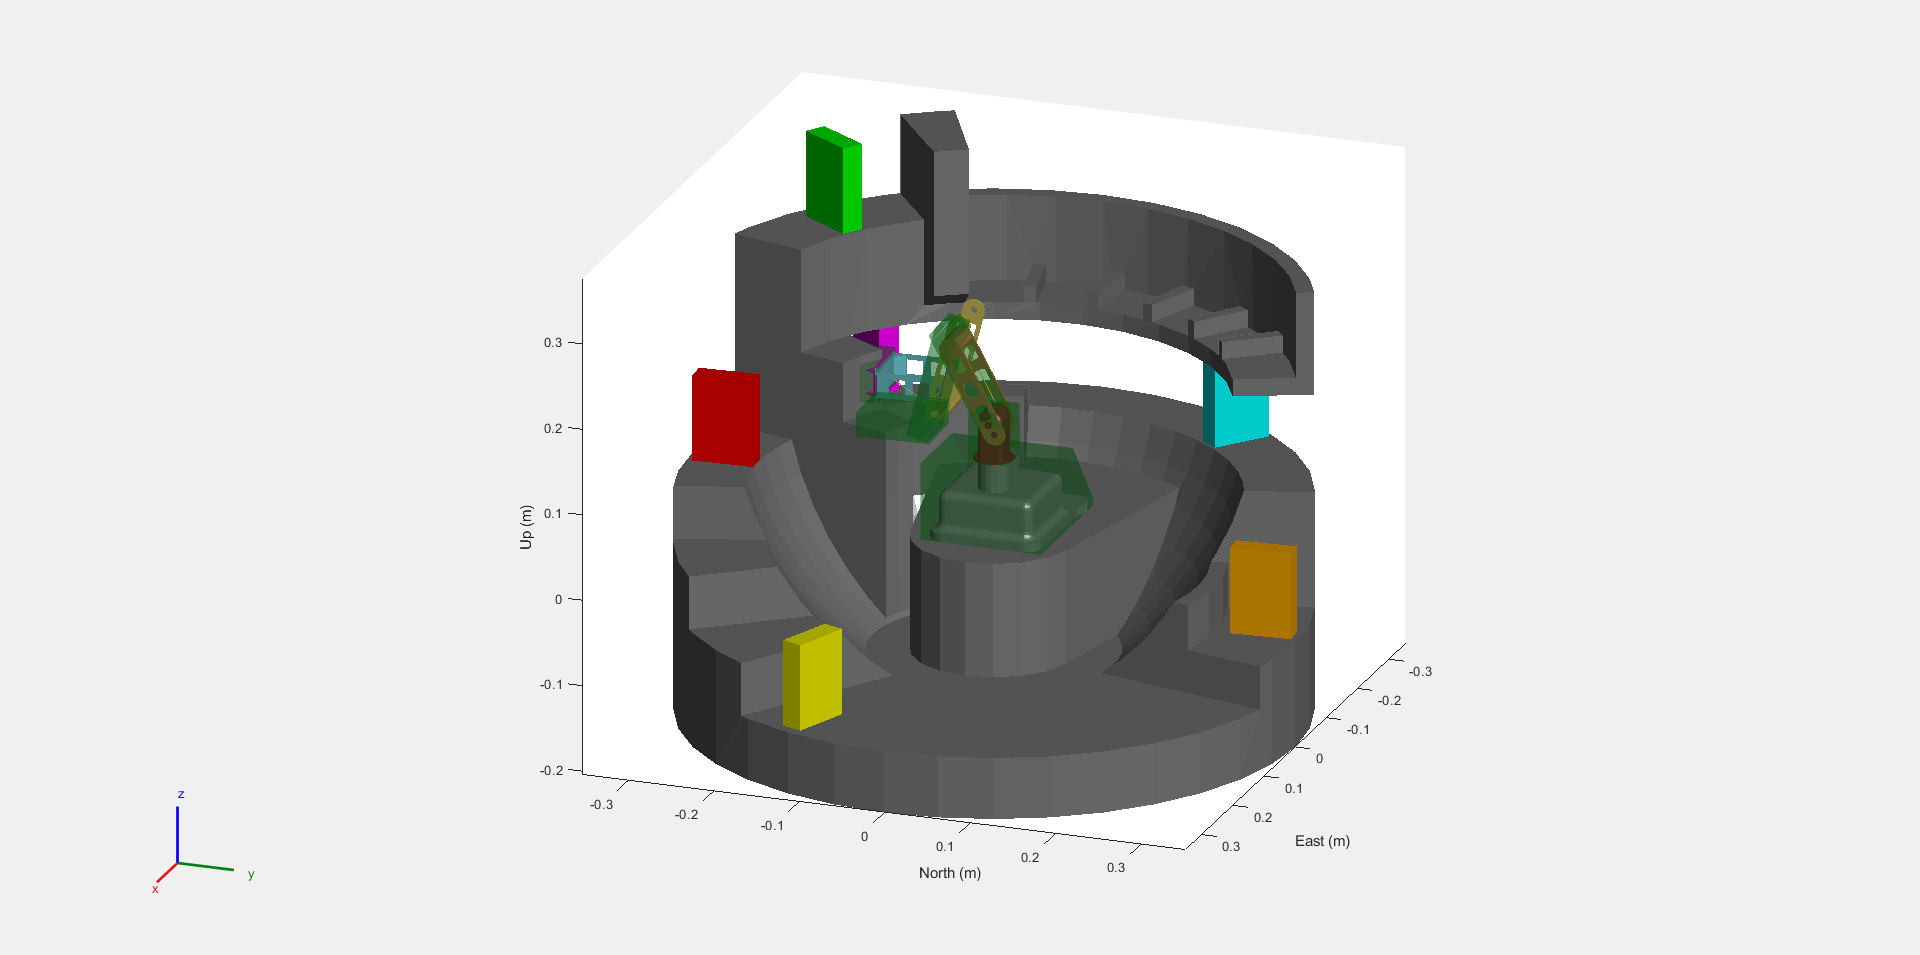


numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
% Dynamically select final_angles for each configuration
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the home config to the first position for the red book
animateRobotTrajectory(scenario, Robot, ax, homeconfig, current_angles(1, :), numSteps);


%% Loop through the 10 points mid-points (10 points)
for i = 1 : numPoints-1

    %% Set the points for the current row and the row below
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    %% Move between the two points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end


%% Attach the book
attach(Robot, books{1}.name, "End_Effector", ...
    'ChildToParentTransform', customTransform);


%% Move between mid-point to draw the book back
animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);

% Loop through all consecutive points in reverse order for the current angles
for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :)

    t = numSteps_mid;


    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, t);

end

current_point = secondPoint;

numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

%%%% Move between the mid-points to setup placing the book down


animateRobotTrajectory(scenario, Robot, ax, current_point, mid_angles_1(1, :), numSteps);
animateRobotTrajectory(scenario, Robot, ax, mid_angles_1(1, :), mid_angles_1(2, :), numSteps);
animateRobotTrajectory(scenario, Robot, ax, mid_angles_1(2, :), current_angles(i, :), numSteps);


for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

detach(Robot);

for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

last_point = current_angles(1, :);

### 5.2 - Book 2

%%%% Book 2 pick up and place down
%%%% Set loop number to 2
k = 2

numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
% Dynamically select final_angles for each configuration
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the home config to the first position
animateRobotTrajectory(scenario, Robot, ax, last_point, current_angles(1, :), numSteps);

%% Loop through the 10 points mid-points (10 points)
for i = 1 : numPoints-1
    
    %% Set the points for the current row and the row below
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);
    
    %% Move between the two points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end


% %% 1) Approach the book until collision
% q_pre   = current_angles(end,:);              % last via-point before grasp  
% q_grasp = eval(['final_angles_' num2str(k)]); % your precomputed grasp config  
% q_grasp = q_grasp(1,:);                       % first row = actual grasp
% 
% nSteps_contact = 30;
% delta = (q_grasp - q_pre) / nSteps_contact;
% 
% q_curr = q_pre;
% for i = 1:nSteps_contact
%     q_curr = q_curr + delta;
%     move(Robot, "joint", q_curr);
%     show3D(scenario, Collisions="on"); drawnow
% 
%     % Check for a collision between the TCP sphere and the book
%     if checkCollision(Robot, books{k}.name, IgnoreSelfCollision="on")
%         break
%     end
% end

%% 2) Now we’re “touching” the book — attach it
attach(Robot, books{k}.name, "End_Effector", ...
    'ChildToParentTransform', customTransform);


%% Loop through and rotate the base ONLY
currentPoint = secondPoint;

for i = 1:20
    nextPoint = currentPoint;
    nextPoint(1) = nextPoint(1) + 2;
    animateRobotTrajectory(scenario, Robot, ax, currentPoint, nextPoint, numSteps_mid);
    currentPoint = nextPoint;
end

%% Loop through the 10 points in reverse (10 points)
for i = numPoints-1 : -1 : 1
    
    %% Set the points for the current row and the row above
    firstPoint = purp_mid_bring_back(i+1, :);
    secondPoint = purp_mid_bring_back(i, :);
    
    %% Move between the two points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

currentPoint = secondPoint;
%% Make the robot go to the position with a slightly smaller radius

numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

animateRobotTrajectory(scenario, Robot, ax, currentPoint, mid_angles_2(1, :),  numSteps);
animateRobotTrajectory(scenario, Robot, ax, mid_angles_2(1, :), mid_angles_2(2, :),  numSteps);
animateRobotTrajectory(scenario, Robot, ax, mid_angles_2(2, :), current_angles(1, :),  numSteps);

for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);
    
    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

detach(Robot);

for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end


### 5.3 - Book 3

%%%% Book 3 pick up and place down
%%%% Set loop number to 3
k = 3

numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
% Dynamically select final_angles for each configuration
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the home config to the first position
animateRobotTrajectory(scenario, Robot, ax, secondPoint, [-56.1146055033277, -80, 0, 0], numSteps);
animateRobotTrajectory(scenario, Robot, ax, [-56.1146055033277, -80, 0, 0], current_angles(1, :),  numSteps);

currentPoint = current_angles(1, :);

numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

%% Attach the book
attach(Robot, books{k}.name, "End_Effector", ...
    'ChildToParentTransform', customTransform);

animateRobotTrajectory(scenario, Robot, ax, currentPoint, [-56.1146055033277, -80, 0, 0],  numSteps);
animateRobotTrajectory(scenario, Robot, ax, [-56.1146055033277, -80, 0, 0], current_angles(1, :),  numSteps);

for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);
    
    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

detach(Robot);

for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end



### 5.3 - Book 4

%%%% Book 3 pick up and place down
%%%% Set loop number to 3
k = 4

numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
% Dynamically select final_angles for each configuration
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the home config to the first position
animateRobotTrajectory(scenario, Robot, ax, secondPoint, mid_point, numSteps);
animateRobotTrajectory(scenario, Robot, ax, mid_point, current_angles(1, :), numSteps);

currentPoint = current_angles(1, :);

numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

%% Attach the book
attach(Robot, books{k}.name, "End_Effector", ...
    'ChildToParentTransform', customTransform);

animateRobotTrajectory(scenario, Robot, ax, currentPoint, mid_point,  numSteps);
animateRobotTrajectory(scenario, Robot, ax, mid_point, current_angles(1, :),  numSteps);

for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);
    
    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

detach(Robot);

for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end


### 5.3 - Book 5

%%%% Book 3 pick up and place down
%%%% Set loop number to 3
k = 5

numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
% Dynamically select final_angles for each configuration
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the home config to the first position
animateRobotTrajectory(scenario, Robot, ax, secondPoint, current_angles(1, :), numSteps*2);

currentPoint = current_angles(1, :);

numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

%% Attach the book
attach(Robot, books{k}.name, "End_Effector", ...
    'ChildToParentTransform', customTransform);

animateRobotTrajectory(scenario, Robot, ax, currentPoint, current_angles(1, :),  numSteps*2);;

for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);
    
    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

detach(Robot);

for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

last_point = current_angles(1, :);


### 5.3 - Book 6

%%%% Book 2 pick up and place down
%%%% Set loop number to 2
k = 6

numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
% Dynamically select final_angles for each configuration
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the home config to the first position
animateRobotTrajectory(scenario, Robot, ax, last_point, current_angles(1, :), numSteps);

%% Loop through the 10 points mid-points (10 points)
for i = 1 : numPoints-1
    
    %% Set the points for the current row and the row below
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);
    
    %% Move between the two points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end


%% Attach the book
attach(Robot, books{k}.name, "End_Effector", ...
    'ChildToParentTransform', customTransform);

%% Loop through the 10 points in reverse (starting from the last point)
for i = numPoints-1 : -1 : 1
    
    %% Set the points for the current row and the row above (in reverse order)
    firstPoint = current_angles(i+1, :);  % Now the 'first' point is the next one
    secondPoint = current_angles(i, :);   % The 'second' point is the previous one
    
    %% Move between the two points (backward)
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end


currentPoint = secondPoint;
%% Make the robot go to the position with a slightly smaller radius

numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

animateRobotTrajectory(scenario, Robot, ax, currentPoint, mid_angles_2(1, :),  numSteps);
animateRobotTrajectory(scenario, Robot, ax, mid_angles_2(1, :), mid_angles_2(2, :),  numSteps);
animateRobotTrajectory(scenario, Robot, ax, mid_angles_2(2, :), current_angles(1, :),  numSteps);

for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);
    
    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

detach(Robot);

for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
end

animateRobotTrajectory(scenario, Robot, ax, secondPoint, homeconfig, numSteps);

## A) Functions:

### A.1 Radius and Height

function results = calculateResults(bookPositions, L1)
    
    % Get the number of rows
    numRows = size(bookPositions, 1);

    % Pre-allocate the results matrix for efficiency
    % It will have the same number of rows as bookPositions, but only 2 columns
    results = zeros(numRows, 2);

    % Loop through each row of the bookPositions matrix
    for i = 1:numRows
        % Extract the first element (a) and second element (b) from the current row
        a = bookPositions(i, 1);
        b = bookPositions(i, 2);

        % Calculate the radius r = sqrt(a^2 + b^2)
        radius = sqrt(a^2 + b^2);
        % Alternatively, you can use hypot(a, b), which is numerically more robust
        % radius = hypot(a, b);

        % Assign the calculated radius to the first column of the results matrix
        results(i, 1) = radius;

        % Assign the third element from the original row to the second column
        results(i, 2) = bookPositions(i, 3);

        results(i, 2) = results(i, 2) - L1;
    end

    % Display the final results matrix
    disp('Results Matrix (Radius, Original Z):');
    disp(results);

end

### A.2 Anmiate Robot Functon

%function animateRobotTrajectory(scenario, Robot, ax, q_start_deg, q_end_deg, numSteps, hideFrames)
function animateRobotTrajectory(scenario, Robot, ax, q_start_deg, q_end_deg, numSteps)
    
    if nargin < 7
        hideFrames = true;
    end

    % Ensure input vectors are row vectors
    q_start_deg = reshape(q_start_deg, 1, []);
    q_end_deg = reshape(q_end_deg, 1, []);

    % Pad to 6 joints if needed (e.g. robot expects 6 DOF input)
    if length(q_start_deg) < 4
        q_start_deg = [q_start_deg, zeros(1, 4 - length(q_start_deg))];
    end
    if length(q_end_deg) < 4
        q_end_deg = [q_end_deg, zeros(1, 4 - length(q_end_deg))];
    end

    % Convert degrees to radians
    q_start = deg2rad(q_start_deg);
    q_end = deg2rad(q_end_deg);

    % Wrap angle differences to ensure shortest path
    delta = wrapToPi(q_end - q_start);  % ensures minimal rotation

    % Time parameter [0, 1]
    t = linspace(0, 1, numSteps);
    s = 0.5 * (1 - cos(pi * t));  % Cosine ease-in-out

    % Interpolate trajectory
    q_traj = q_start + s' .* delta;

    % ---- Animate ----
    for k = 1:numSteps

        move(Robot, "joint", q_traj(k, :));

        cla(ax);
        show3D(scenario, Collisions="on");
        light(ax, 'Position', [1 1 1], 'Style', 'infinite');
        view(ax, 110, 20);

        if hideFrames
            gfx_Frames = findall(ax, 'FaceColor', 'flat');
            set(gfx_Frames, 'FaceAlpha', 0);
            gfx_Base_Frame = findall(ax, 'DisplayName', 'Base_Link');
            set(gfx_Base_Frame, 'FaceAlpha', 0);
        end

        drawnow;
        pause(0.02);

    end

end

### A.3 Find Theta 1

function theta1_values = calculateTheta1(bookPositions, centre)
    numRows = size(bookPositions, 1);
    theta1_values = zeros(numRows, 1);

    for i = 1:numRows
        P = bookPositions(i, :);
        P(1) = -(P(1) - centre(1));
        P(2) = P(2) - centre(2);
        theta1 = atan2(P(2), P(1));
        theta1_values(i) = rad2deg(theta1);
    end
end

### A.4 Find Theta 2 (All Books)

function theta_values = calculateTheta234(results, L2, L3, L4)
    numRows = size(results, 1);
    theta_values = zeros(numRows, 3);

    for i = 1:numRows
        r_target = results(i, 1);
        z_target = results(i, 2);
        z_target = -z_target;  % Flip the z-coordinate based on the setup

        % Calculate the angle to the target in the plane (XY)
        angle_to_target = atan2(z_target, r_target);

        % Calculate the wrist position
        wrist_r = r_target - L4 * cos(angle_to_target);
        wrist_z = z_target - L4 * sin(angle_to_target);

        % Calculate the distance from the wrist to the base
        d = sqrt(wrist_r^2 + wrist_z^2);

        % Solve for theta3 using the law of cosines
        cos_theta3 = (d^2 - L2^2 - L3^2) / (2 * L2 * L3);
        cos_theta3 = min(max(cos_theta3, -1), 1);
        theta3 = acos(cos_theta3);

        % Solve for theta2
        alpha = atan2(wrist_z, wrist_r);
        cos_beta = (L2^2 + d^2 - L3^2) / (2 * L2 * d);
        cos_beta = min(max(cos_beta, -1), 1);
        beta = acos(cos_beta);
        theta2 = alpha - beta;

        % Calculate theta4 based on previous angles to keep the last limb horizontal
        % Theta4 is adjusted relative to theta2 and theta3 to ensure it remains horizontal with the ground

        % Calculate the orientation of the third limb (theta2 + theta3 combined)
        orientation_of_third_limb = theta2 + theta3;
        
        % Ensure the last joint (theta4) makes the final limb horizontal relative to the ground
        theta4 = orientation_of_third_limb;  % Adjust to make the final joint horizontal

        % Store the calculated angles in the output array, converting to degrees
        theta_values(i, 1) = rad2deg(theta2);  % Theta 2
        theta_values(i, 2) = rad2deg(theta3);  % Theta 3
        theta_values(i, 3) = rad2deg(theta4);  % Theta 4

    end

end

### A.5 Find Theta 2 (Books 3, 4 & 5)

% Function to calculate Theta 2, 3, and 4
function theta_values = calculateTheta234_bend(results, L2, L3, L4)
    numRows = size(results, 1);
    theta_values = zeros(numRows, 3);

    for i = 1:numRows
        r_target = results(i, 1);
        z_target = results(i, 2);
        z_target = -z_target;

        angle_to_target = atan2(z_target, r_target);

        wrist_r = r_target - L4 * cos(angle_to_target);
        wrist_z = z_target - L4 * sin(angle_to_target);

        d = sqrt(wrist_r^2 + wrist_z^2);

        cos_theta3 = (d^2 - L2^2 - L3^2) / (2 * L2 * L3);
        cos_theta3 = min(max(cos_theta3, -1), 1);
        theta3 = acos(cos_theta3);

        alpha = atan2(wrist_z, wrist_r);
        cos_beta = (L2^2 + d^2 - L3^2) / (2 * L2 * d);
        cos_beta = min(max(cos_beta, -1), 1);
        beta = acos(cos_beta);
        theta2 = alpha - beta;

        theta4 = angle_to_target - theta2 - theta3;

        theta_values(i, 1) = rad2deg(theta2);
        theta_values(i, 2) = rad2deg(theta3);
        theta_values(i, 3) = rad2deg(theta4);

    end

end

## Submission Instructions and Deadline

**Deadline: **Week 23 - Thursday @15:00 - 01/05/2025

**You will submit:**

- The complete code of your solution as a MATLAB Live Script, please also include outputs (e.g. do not clear the outputs after processing)

- Please, export your MATLAB Live Script as a PDF with the same file name. Only include outputs that are necessary to explain your process or those that show important milestones in the coursework (basically, please don't output everything making the document huge)

- Please refer to the hadnout for further instructions.

**MECH3465 CW2 2025 **| Written by ***Louie Burns & Dan Nehushtan***

*Email: ****mn22lb@leeds.ac.uk & mn22dn@leeds.ac.uk***